# Exercise 2. Numerical Integration and Differentiation

Your task for this exercise is to complete the program so that it executes correctly by filling in the correct statements. You will be given a data file obtained from measuring the current through a series RC circuit. The source voltage, $V_S=5V$, the capacitance, $C=1000\;\mu F$, and the resistance, $R=10\;\;\Omega$. The data file is a text file with two sets of data arranged into two columns. The first set (column) is the time variable, while the second set (column) is the current variable. 

*Note: If you find anything new in this activity, look them up in the MATLAB's HELP feature.*

clear;

#### Importing the Data File

The first step is to load the data into the MATLAB workspace. The data is saved in the file $'current.txt'$. Use the $importdata()$ command to load the data to the variable $A$. DO NOT PUT A SEMICOLON at the end of the statement.

A = importdata("current.txt")

A = struct with fields:
          data: [101×2 double]
      textdata: {'Time (ms)'  'Current (A)'}
    colheaders: {'Time (ms)'  'Current (A)'}


If you look at the panel to the right, you will see that $A$ is a $struct$ with the fields $data$, $textdata$ and $colheaders$. What we want is to extract the $data$ which is a 101 x 2 matrix. You can take a look at its contents by using the $type$ command in the field below. Type $type$ and then $space$ and then the file name. DO NOT PUT A SEMICOLON at the end of the statement.

type current.txt

Time (ms),Current (A)
0,0.513913818536575
0.001,0.464976792573791
0.002,0.418373139626029
0.003,0.379881469182837
0.004,0.35415415008789
0.005,0.304935281092103
0.006,0.280002396447018
0.007,0.257232798082399
0.008,0.236415907338517
0.009,0.22083751263859
0.01,0.193321730990302
0.011,0.175183911363074
0.012,0.165520804755598
0.013,0.145624105833161
0.014,0.140515028991961
0.015,0.120895320321845
0.016,0.110910348739782
0.017,0.101090375114676
0.018,0.0872388196057536
0.019,0.0764953542594987
0.02,0.0690153078904845
0.021,0.0789960328225825
0.022,0.0600649328945601
0.023,0.0673613370610892
0.024,0.0595936785048646
0.025,0.0584987591728065
0.026,0.0558968292455595
0.027,0.0363965419408249
0.028,0.0382830342096291
0.029,0.0471228666225047
0.03,0.0377894147036395
0.031,0.0404527967858576
0.032,0.0300257100979191
0.033,0.0187234452044005
0.034,0.0291442418688589
0.035,0.0197205989733819
0.036,0.024210540479179
0.037,0.0268616024623145
0.038,0.0233337017509815
0.039,0.0218882846388072
0.04,0

The first line in the data is the $colheaders$ or the column header, which are the labels for the data sets.

#### Extracting and Plotting the Data Set

Extracting the data from the variable $A$ is very easy. Let's first define the new variables $t$ for time and $cur$ for the current. The first column of the variable $data$ in $struct$ $A$ is the time data, while the second column is the current data. The command below assigns column 1 (time data) to the variable $t$.

t = A.data(:,1);    % DO NOT CHANGE THIS STATEMENT

Assign the column 2 (current data) to the variable $cur$.

cur = A.data(:,2);

Plot the current vs time using the marker 'o' with black color.

plot(t,cur,'ko')

Add a title, an x-axis label and a y-axis label, using font sizes of 15 units.

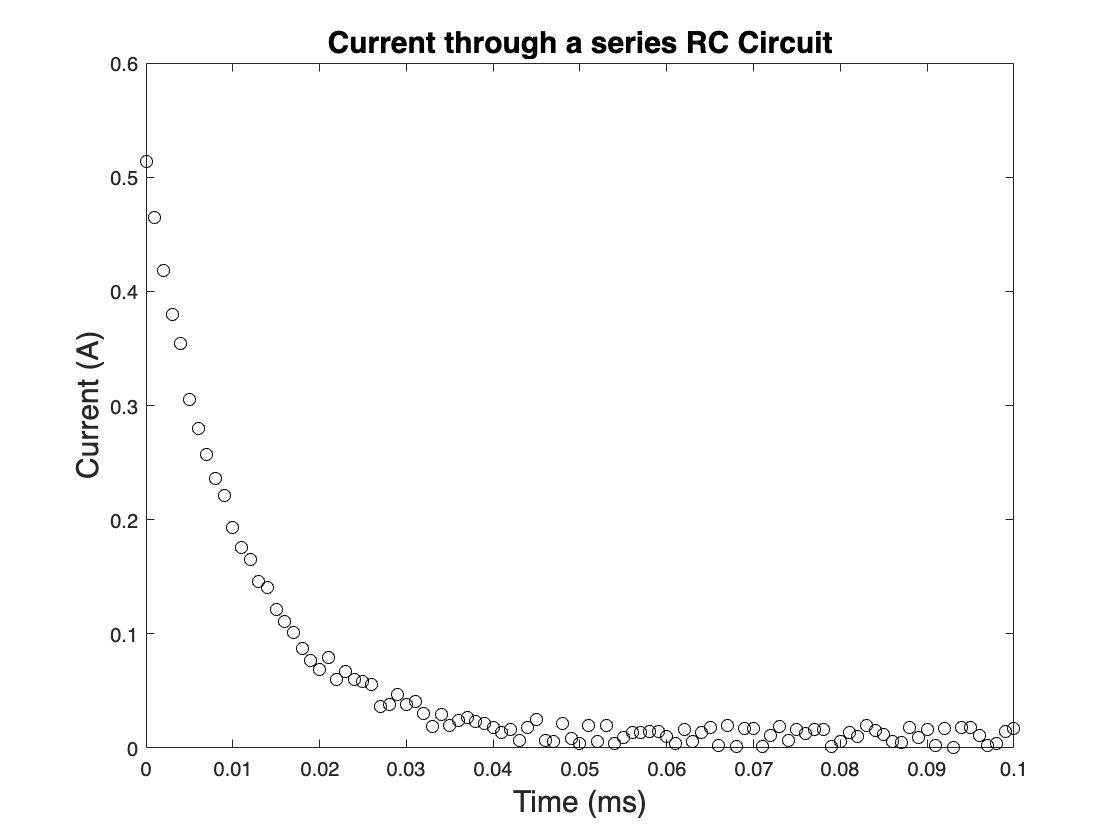

title("Current through a series RC Circuit","FontSize",15)
xlabel("Time (ms)","FontSize",15)
ylabel("Current (A)","FontSize",15)

#### TASK 1. How much charge passed through the series RC circuit over the whole measured time period?

To estimate the total charge, you need to integrate over the whole time period. In other words,


$$Q=\int_{t=0}^{t=t_{\max } } i\left(t\right)\textrm{dt}$$


you need to integrate over the whole time period and determine the total charge. In the video lecture, we used a continuous function as an example. However, we saw that as we increased the interval size, $h$, the integration becomes more accurate. For discrete functions or discrete data sets such as the one that we have now, the interval size is already pre-defined. In the field below, write down the numerical value of the interval size and assign that value to the variable, $h$.

h = 0.001;

To numerically integrate the data for current using the trapezoidal rule, we have shown that the numerical solution is given by


$$I=h_1 \frac{f\left(x_1 \right)+f\left(x_2 \right)}{2}+h_2 \frac{f\left(x_2 \right)+f\left(x_3 \right)}{2}+\ldotp \ldotp \ldotp +h_{n-1} \frac{f\left(x_{n-1} \right)+f\left(x_n \right)}{2}$$


or if we group terms and assume that the intervals are the same, we have


$$I=\frac{h}{2}\left\lbrack f\left(x_1 \right)+2\sum_{i=2}^{n-1} f\left(x_i \right)+f\left(x_n \right)\right\rbrack$$


In the field below, implement the trapezoidal rule to get the total charge for the whole time period. Use the variable, $Q$, for the total charge. 

% sumQ = 0;
% for i = 1:length(cur)-1
%     sumQ = sumQ + (cur(i) + cur(i+1))/2;
% end
% Q = h*sumQ
Q = mytrapz( voltage, h )

Q = 0.0060

Now, let's check if you got the correct answer. MATLAB has a built-in function for computing the integral of a function using the trapezoidal rule. The function is called '$trapz()$'. Check out the syntax of the $trapz()$ function using HELP. Use the variable, $Qtrapz$, to save the value of the total charge in.

Qtrapz = trapz(t,cur)

Qtrapz = 0.0060

If you did this correctly, $Q$ should be equal to $Qtrapz$.

As a follow-up question, how many electrons passed through the RC circuit over the whole measured time period? Use the variable, $n$, for the number of electrons.

n = Q/1.609e-19

n = 3.7554e+16

ntrapz = Qtrapz/1.609e-19

ntrapz = 3.7554e+16

#### TASK 2. What is the time dependence of the charge of the series RC circuit?

In this task, we need to get a plot of the charge as a function of time from the plot of the current as a function of time. To facilitate faster and use our time efficiently, we are going to use the function '$cumtrapz()$'. Check out the syntax of the $cumtrapz()$ function using HELP. 

In the field below, use MATLAB's built-in function $cumtrapz$ to get the time dependence of the charge. Use the variable, $q$, for the time-dependent charge.

q = cumtrapz(t,cur);
size(cur)

ans =    101     1


size(q)

ans =    101     1


Plot the charge, $q$, versus time, $t$ using the marker '*' (asterisk) with black color.

plot(t,q,'k*')

Estimate the capacitor charge at the time equal to the time constant?

% Write your answer here: 

Add a title, an x-axis label and a y-axis label, using font sizes of 15 units.

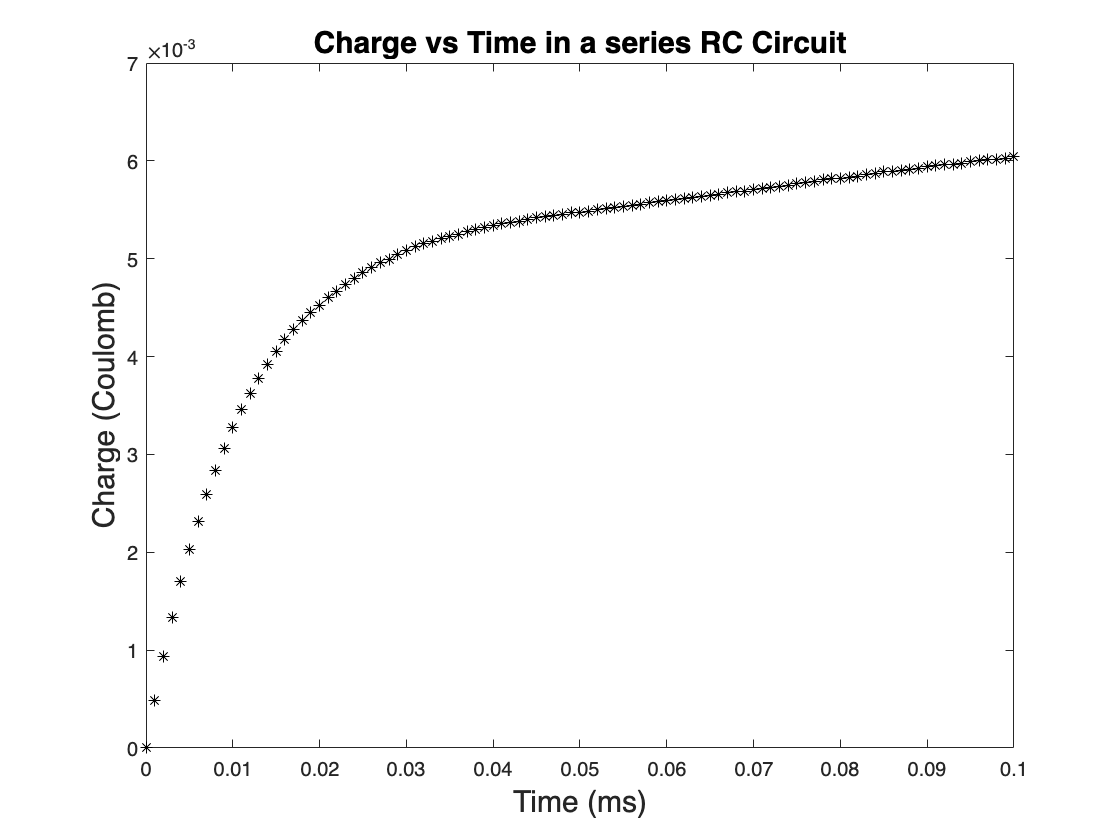

title("Charge vs Time in a series RC Circuit","FontSize",15)
xlabel("Time (ms)","FontSize",15)
ylabel("Charge (Coulomb)","FontSize",15)

#### TASK 3. Compare with Theory

Given the source voltage, $V_S=5V$, the capacitance, $C=1000\;\mu F$, and the resistance, $R=10\;\;\Omega$. Define these variables and their corresponding values in the field below. Solve for the value of the time constant, $\tau$, as well.

Vs = 5; % unit of Volts
R = 10; % unit of Ohm
C = 1000e-6; % unit of Farad
tau = R*C % unit of seconds

tau = 0.0100

The expression for the charge of a capacitor given by


$$q\left(t\right)=CV_S \left\lbrack 1-\exp \left(-\frac{t}{\textrm{RC}}\right)\right\rbrack$$


Given the circuit element values, implement the theoretical expression for the charge of a capacitor in MATLAB by writing down the correct MATLAB statement below. You may need to review the theoretical equation for the charge across the capacitor from your Physics 102 lectures. For the theoretical charge, use the variable, $qtheory$.

qtheory = C*Vs*(1-exp(-t/tau));

Plot the theoretical charge vs time against the experimental result you obtained in Task 2.  In other words, plot the theoretical result and superimposed on this the experimental result. Use a red line for the theoretical plot, with a LineWidth of 3 units. Use the same black asterisk marker for the experimental result. 

plot(t,q,'k*')
hold on
plot(t,qtheory,'r','LineWidth',3)
hold off

Add a title, an x-axis label and a y-axis label, using font sizes of 15 units.

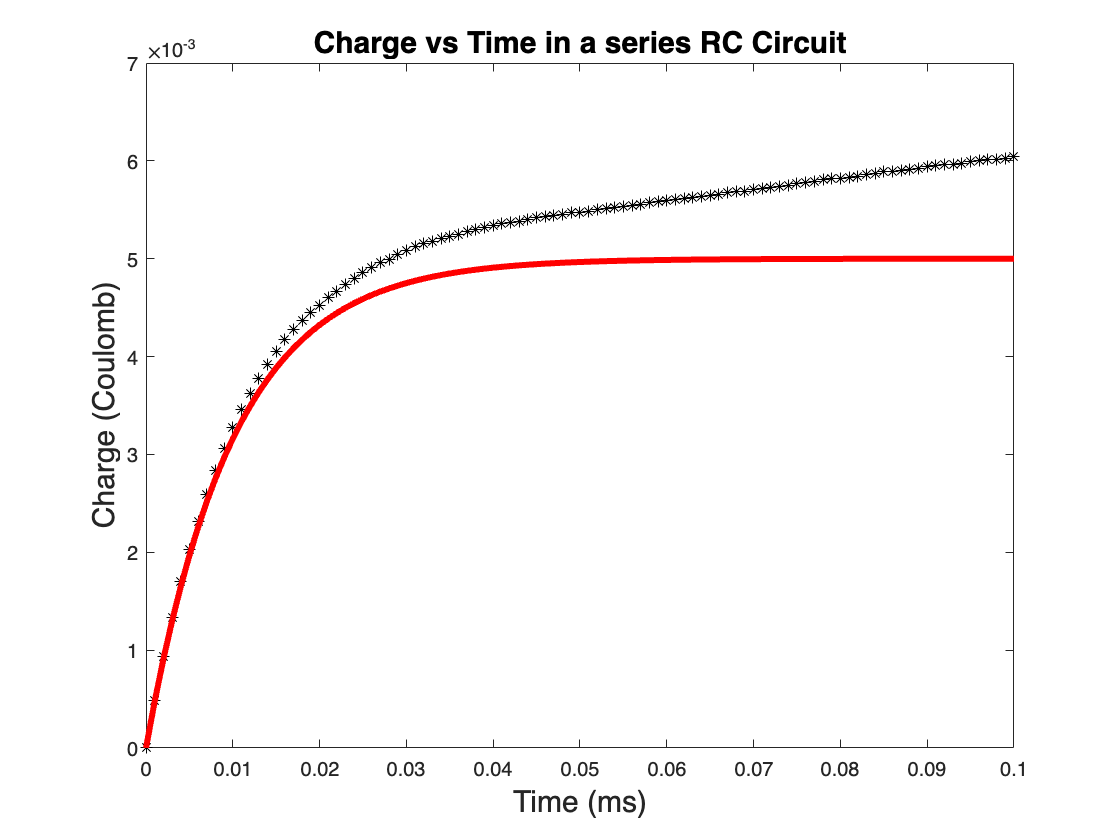

title("Charge vs Time in a series RC Circuit","FontSize",15)
xlabel("Time (ms)","FontSize",15)
ylabel("Charge (Coulomb)","FontSize",15)

The current is then given by the time derivative of this charge expression as

$i\left(t\right)=\frac{\textrm{dq}\left(t\right)}{\textrm{dt}}=\frac{V_S }{R}\exp \left(-\frac{t}{\textrm{RC}}\right)$.

Given the circuit element values, implement the theoretical expression for the current through a capacitor in MATLAB by writing down the correct MATLAB statement below. You may need to review the theoretical equation for the charge across the capacitor from your Physics 102 lectures.

For the theoretical charge, use the variable, $curtheory$.

curtheory = (Vs/R)*exp(-t/tau);

Plot the theoretical current vs time against the experimental result you obtained in Task 1. In other words, plot the theoretical result and superimposed on this the experimental result. Use a red line for the theoretical plot, with a LineWidth of 3 units. Use the same black circle marker for the experimental result. 

plot(t,cur,'ko')
hold on
plot(t,curtheory,'r','LineWidth',3)
hold off

Add a title, an x-axis label and a y-axis label, using font sizes of 15 units.

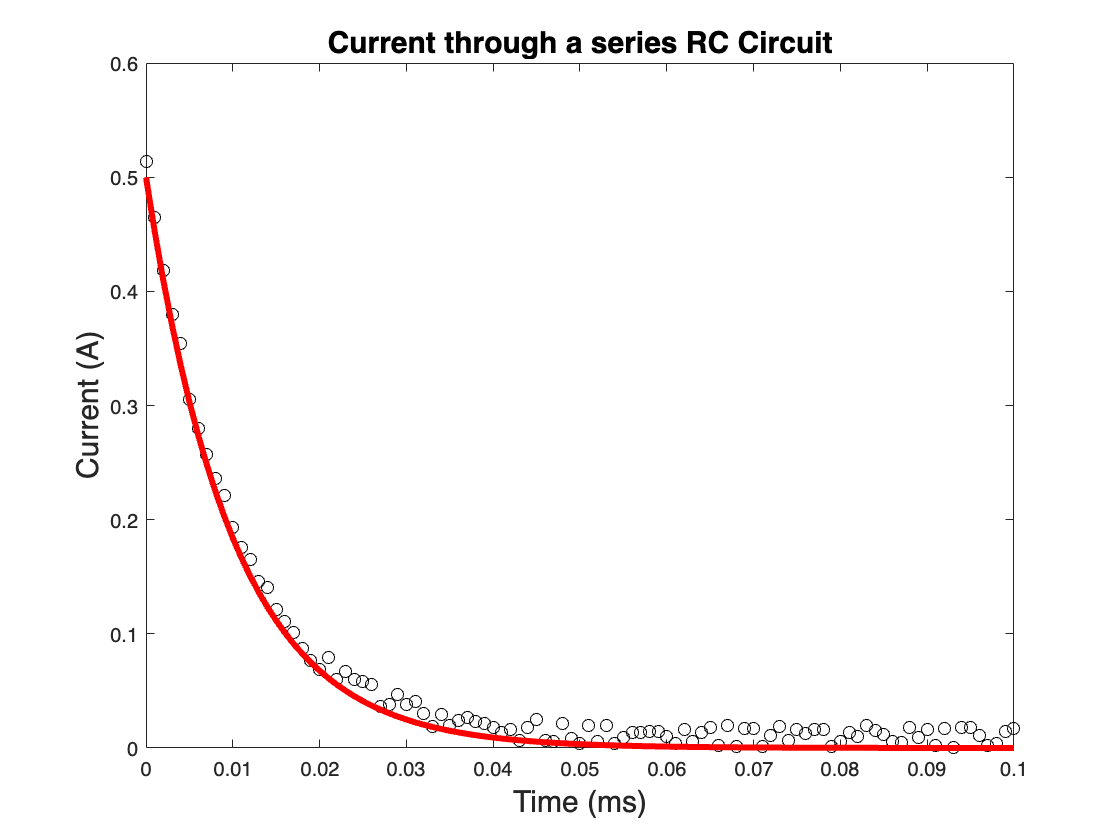

title("Current through a series RC Circuit","FontSize",15)
xlabel("Time (ms)","FontSize",15)
ylabel("Current (A)","FontSize",15)

Notice that there is are discrepancies between theory and experiment. Identify possible sources of errors and explain your hypothesis. 

% Write your answer here:

#### TASK 4. Differentiation

Using any of the differentiation techniques described in the video lecture in our VLE, differentiate the experimental charge vs time data. Use the variable, $curdiff$, for the differentiated charge.

for i = 1:length(cur)-1
    curdiff(i) = (q(i+1)-q(i))/0.001;
end

Compare $curdiff$ with $cur$ by plotting both data in one graph. Use black circles as marker for the variable $cur$ and a red line, with a LineWidth of 3 units, for the variable $curdiff$.

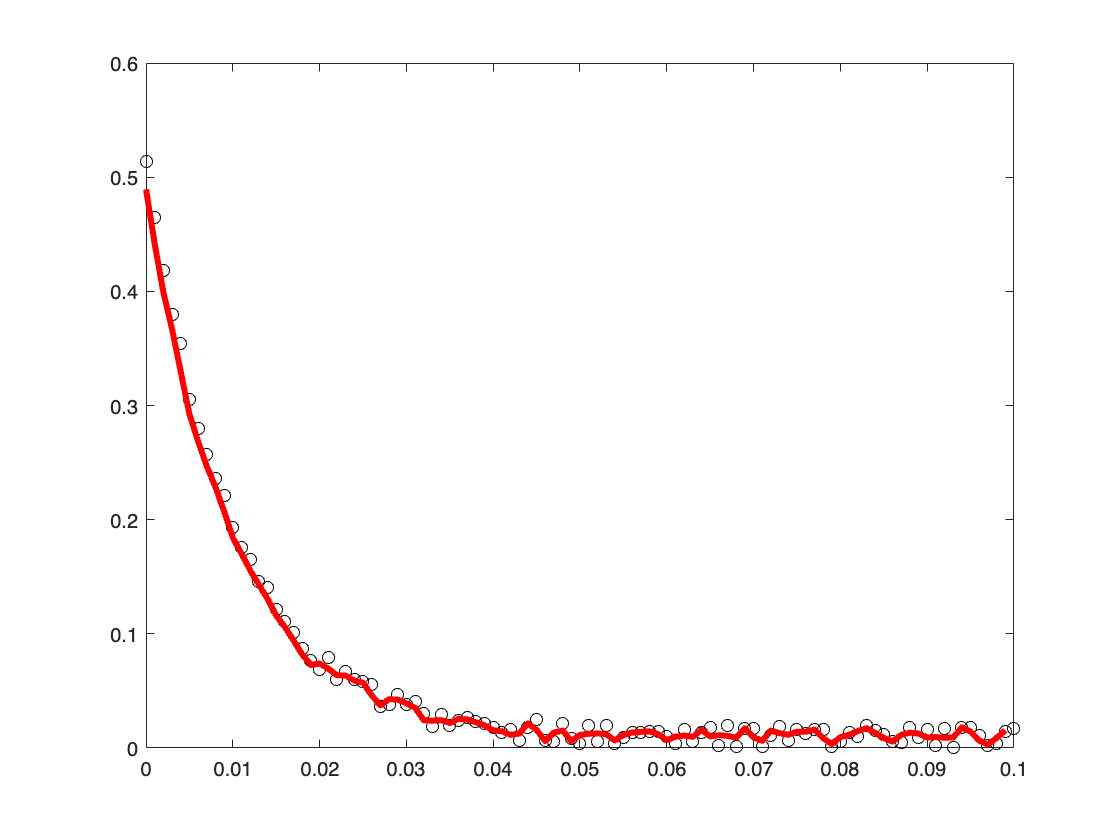

plot(t,cur,'ko')
hold on
plot(t(1:length(cur)-1),curdiff,'r','LineWidth',3)
hold off

How would you describe the accuracy of the between the two data?

% Write your answer here: 

#### TASK 5. Saving the Data to File

You are going to save five sets of data to a text file. These are the time, $t$, the experimental charge, $q$, the theoretical charge, $qtheory$, the experimental current, $cur$, and the theoretical current, $curtheory$. Notice, that these variables are all column matrices. In the field below, show that any one of these variables is a column matrix.

size(cur)

ans =    101     1


If any of these is a row matrix, you need to convert each of them to column matrices. To do this, you get the transpose of each of these matrices. Here's an example. In the example, I assigned a new variable $A$ to be the transpose of the variable, $t$.

% A = t';

We then create a table $T$, which includes the column matrices $t$, $q$, $qtheory$, $cur$, and $curtheory$ in that order. The 'VariableNames' adds an extra line at the beginning giving labels to each column. 

Use the $table()$ command to write the the variables $t$, $q$, $qtheory$, $cur$, and $curtheory$ to the new variable $T$. Use 'VariableNames' as an option with the following values 

{'Time (ms)', 'Experimental Charge (C)','Theoretical Charge (C)','Experimental Current (A)','Theoretical Current (A)'}

T = table(t, q, qtheory, cur, curtheory, 'VariableNames',...
    {'Time (ms)', 'Experimental Charge (C)','Theoretical Charge (C)',...
    'Experimental Current (A)','Theoretical Current (A)'})

T = 101×5 table
    Time (ms)    Experimental Charge (C)    Theoretical Charge (C)    Experimental Current (A)    Theoretical Current (A)
    _________    _______________________    ______________________    ________________________    _______________________

          0                     0                          0                  0.51391                         0.5        
      0.001            0.00048945                 0.00047581                  0.46498                     0.45242        
      0.002            0.00093112                 0.00090635                  0.41837                     0.40937        
      0.003             0.0013302                  0.0012959                  0.37988                     0.37041        
      0.004             0.0016973                  0.0016484                  0.3

The command $writetable()$ writes the data in the table $T$ to the file 'alldata.txt'. Use the $writetable()$ command to write the contenxt of the variable $T$ to the filename "allmatlabdata.txt".

writetable(T, 'allmatlabdata.txt')

Check if the data was written correctly in the file.

type allmatlabdata.txt

Time (ms),Experimental Charge (C),Theoretical Charge (C),Experimental Current (A),Theoretical Current (A)
0,0,0,0.513913818536575,0.5
0.001,0.000489445305555183,0.000475812909820202,0.464976792573791,0.45241870901798
0.002,0.000931120271655093,0.000906346234610091,0.418373139626029,0.409365376538991
0.003,0.00133024757605953,0.00129590889659141,0.379881469182837,0.370409110340859
0.004,0.00169726538569489,0.0016483997698218,0.35415415008789,0.33516002301782
0.005,0.00202681010128489,0.00196734670143683,0.304935281092103,0.303265329856317
0.006,0.00231927894005445,0.00225594181952987,0.280002396447018,0.274405818047013
0.007,0.00258789653731916,0.00251707348104295,0.257232798082399,0.248292651895705
0.008,0.00283472089002961,0.00275335517941389,0.236415907338517,0.224664482058611
0.009,0.00306334760001817,0.002967151701297,0.22083751263859,0.2032848298703
0.01,0.00327042722183261,0.00316060279414279,0.193321730990302,0.183939720585721
0.011,0.0034546800430093,0.0033356445815096,0.175183